# Aeropéndulo Doble

### Amelia Hoyos, Esteban Álvarez, Gabriela Sandoval, Natalia Gómez

El sistema del aeropéndulo doble consiste en una barra rígida sujeta a un pivote en cuyos extremos están acoplados dos motores con hélices. Cada hélice genera una fuerza de empuje perpendicular a la barra, la cual induce un momento de fuerza que hace girar el sistema alrededor de su pivote, ubiccado en el origen del sistema de referencia. 

Supongamos que la fuerza de empuje $T_1$ genera un momento positivo $\vec{M}_1 = l_1 \times T_1$ y que $T_2$ genera un momento negativo $\vec{M}_2 = l_2 \times T_2$. El centro de gravedad del sistema puede no coincidir con el pivote, por lo que el peso del aeropéndulo también produce un momento de fuerza. Dicho momento viene dado por $\vec{M_3} = mgd\sin(\phi)  $, donde $g$ es la aceleración debida a la gravedad, $m$ es la masa del péndulo, $d$ es la distancia desde el pivote hasta el centro de gravedad, y $\phi$ es el ángulo positivo medido entre el eje $y$ negativo y el eje del péndulo. 

Por último, la fuerza de arrastre del aire, que se opone al movimiento, se modela mediante el término $\vec{M_4} = -b\dot{\theta}$ donde $b$ es el coeficiente de amortiguamiento viscoso del aire, $\theta = \frac{\pi}{2} - \phi$ es el ángulo medido respecto a la horizontal positiva y $\dot{\theta}$ es su velocidad angular.

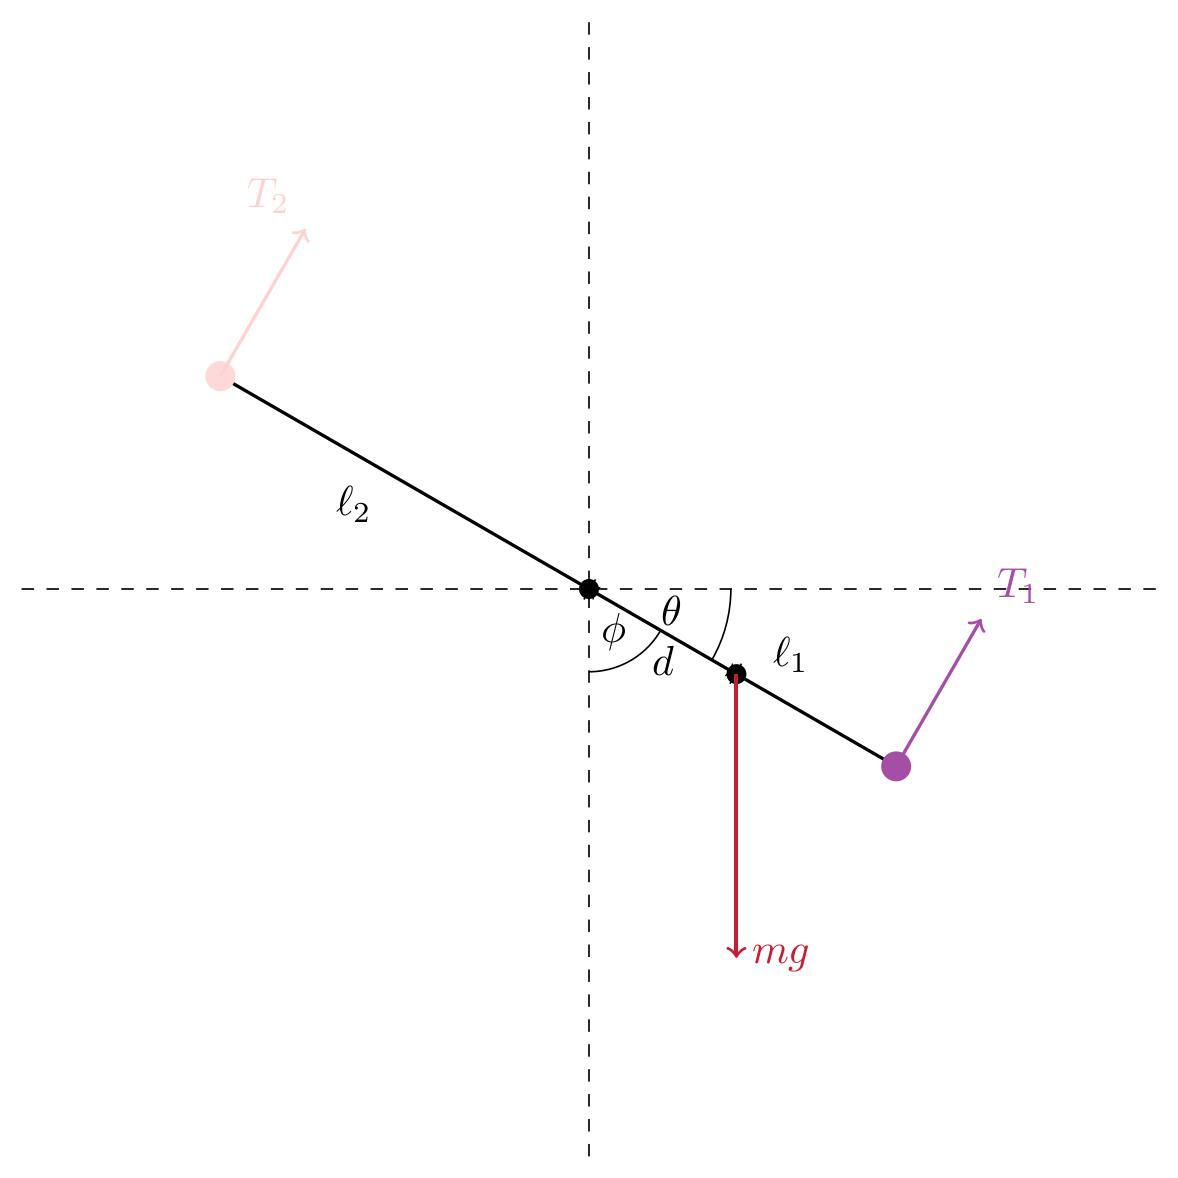

Según la formulación de Newton-Euler que describe la dinámica de sólidos rígidos, 

$J\ddot{\theta} = \sum_{i=1}^4 \vec{M_i} $,

donde $J$ es el momento de inercia rotacional del sistema. La ecuación dinámica del sistema es,

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\sin(\phi) - b\dot{\theta}$.

Podemos reescribir la ecuación como

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\cos\left( \theta\right) - b\dot{\theta}$.

## Simulación del sistema dinámico

Definimos algunos parámetros del sistema.

clear; clc; close all;

Operation terminated by user during closereq (line 18)

Error using close
Interrupt while evaluating DestroyedObject CloseRequestFcn.




% Parámetros físicos
params.mb = 0.1;       % Masa de la barra (kg)
params.m1 = 0.2;       % Masa del rotor 1 (kg)
params.m2 = 0.2;       % Masa del rotor 2(kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.1;        % Coeficiente de amortiguamiento (N·m·s/rad)

%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s

x0 = [theta0; theta_dot0];

function params = aeropendulum_compute_params(params)

    % Longitud total de la barra
    params.L = params.l1 + params.l2;
    
    % Distancia del pivote al centro de gravedad
    params.d = (params.l1 + params.l2)/2 - params.l2;
    
    % Masa total
    params.m = params.mb + params.m1 + params.m2;
    
    % Momento de inercia de la barra
    J_bar = (1/12)*params.mb*params.L^2 + params.mb*params.d^2;
    
    % Momento de inercia de los rotores
    J_r1 = params.m1 * params.l1^2;
    J_r2 = params.m2 * params.l2^2;
    
    % Momento de inercia total
    params.J = J_bar + J_r1 + J_r2;

end

params = aeropendulum_compute_params(params);

El modelo y la forma en como se define la fuerza de empuje se encuentra descrita a continuación


%% ---- Dynamics function ----
function dx = aeropendulum_dynamics(t,x,params, thrust_fun)

Function 'aeropendulum_dynamics' has already been declared within this scope.

    theta = x(1);
    theta_dot = x(2);

    [T1,T2] = thrust_fun(t, theta, theta_dot);

    theta_ddot = (T1*params.l1 - T2*params.l2 - params.m*params.g*params.d*sin(pi/2 - theta) - params.c*theta_dot)/params.J;
    dx = [theta_dot; theta_ddot];
end

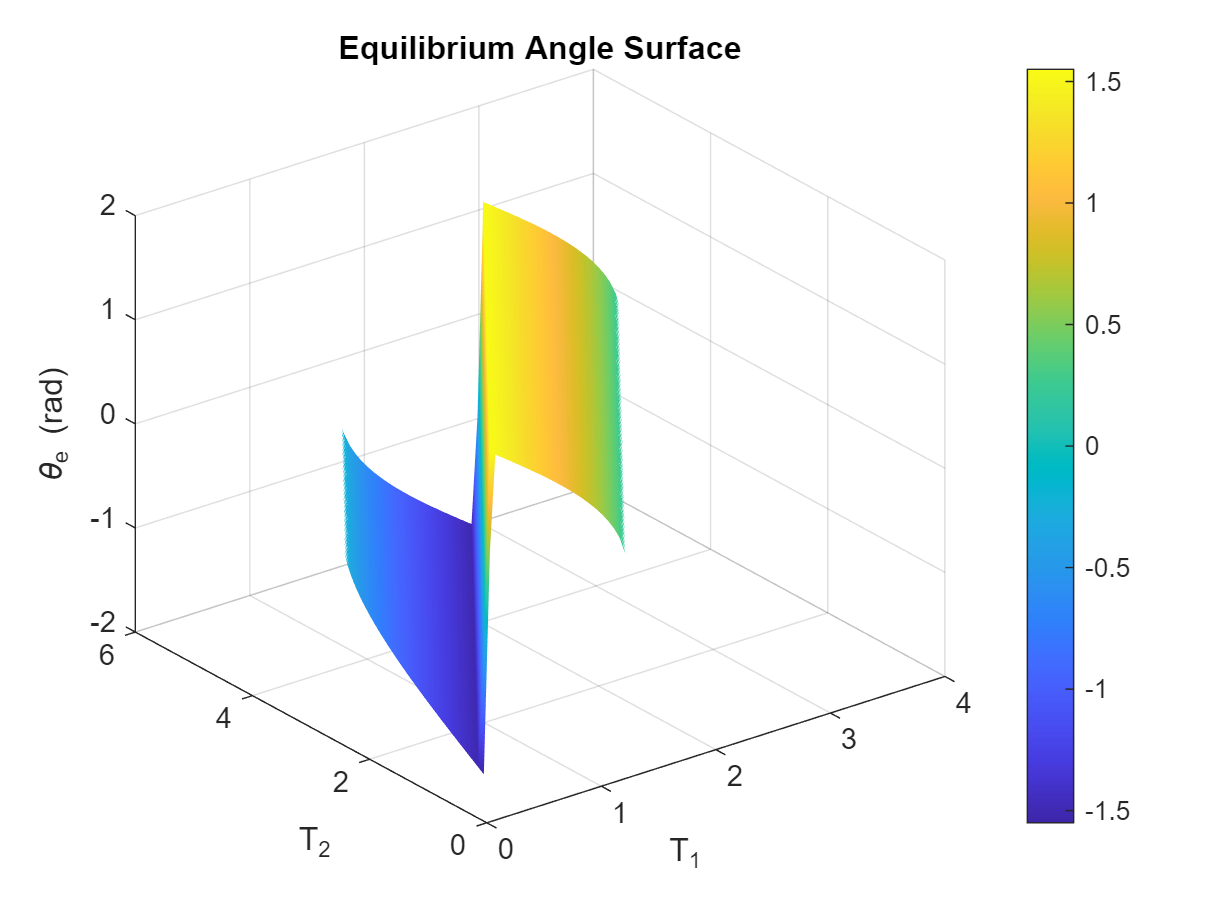

% Ecuación dinámica del aerobalancín
function dx = aeropendulum_dynamics(t,x,params,thrust_fun)
    
    % Entradas:
    %   t           -> tiempo
    %   x           -> vector de estado [theta; theta_dot]
    %   params      -> parámetros físicos del sistema
    %   thrust_fun  -> función de empuje [T1,T2] = thrust_fun(t,theta,theta_dot)
    %
    % Salida:
    %   dx          -> derivada del vector de estado
    
    %% Estados
    theta = x(1);
    theta_dot = x(2);
    

    % Mantener theta en [-pi, pi]
    theta = atan2(sin(theta),cos(theta));
    

eq = 0.6109

    %% Empujes de los rotores

input = 1.0045

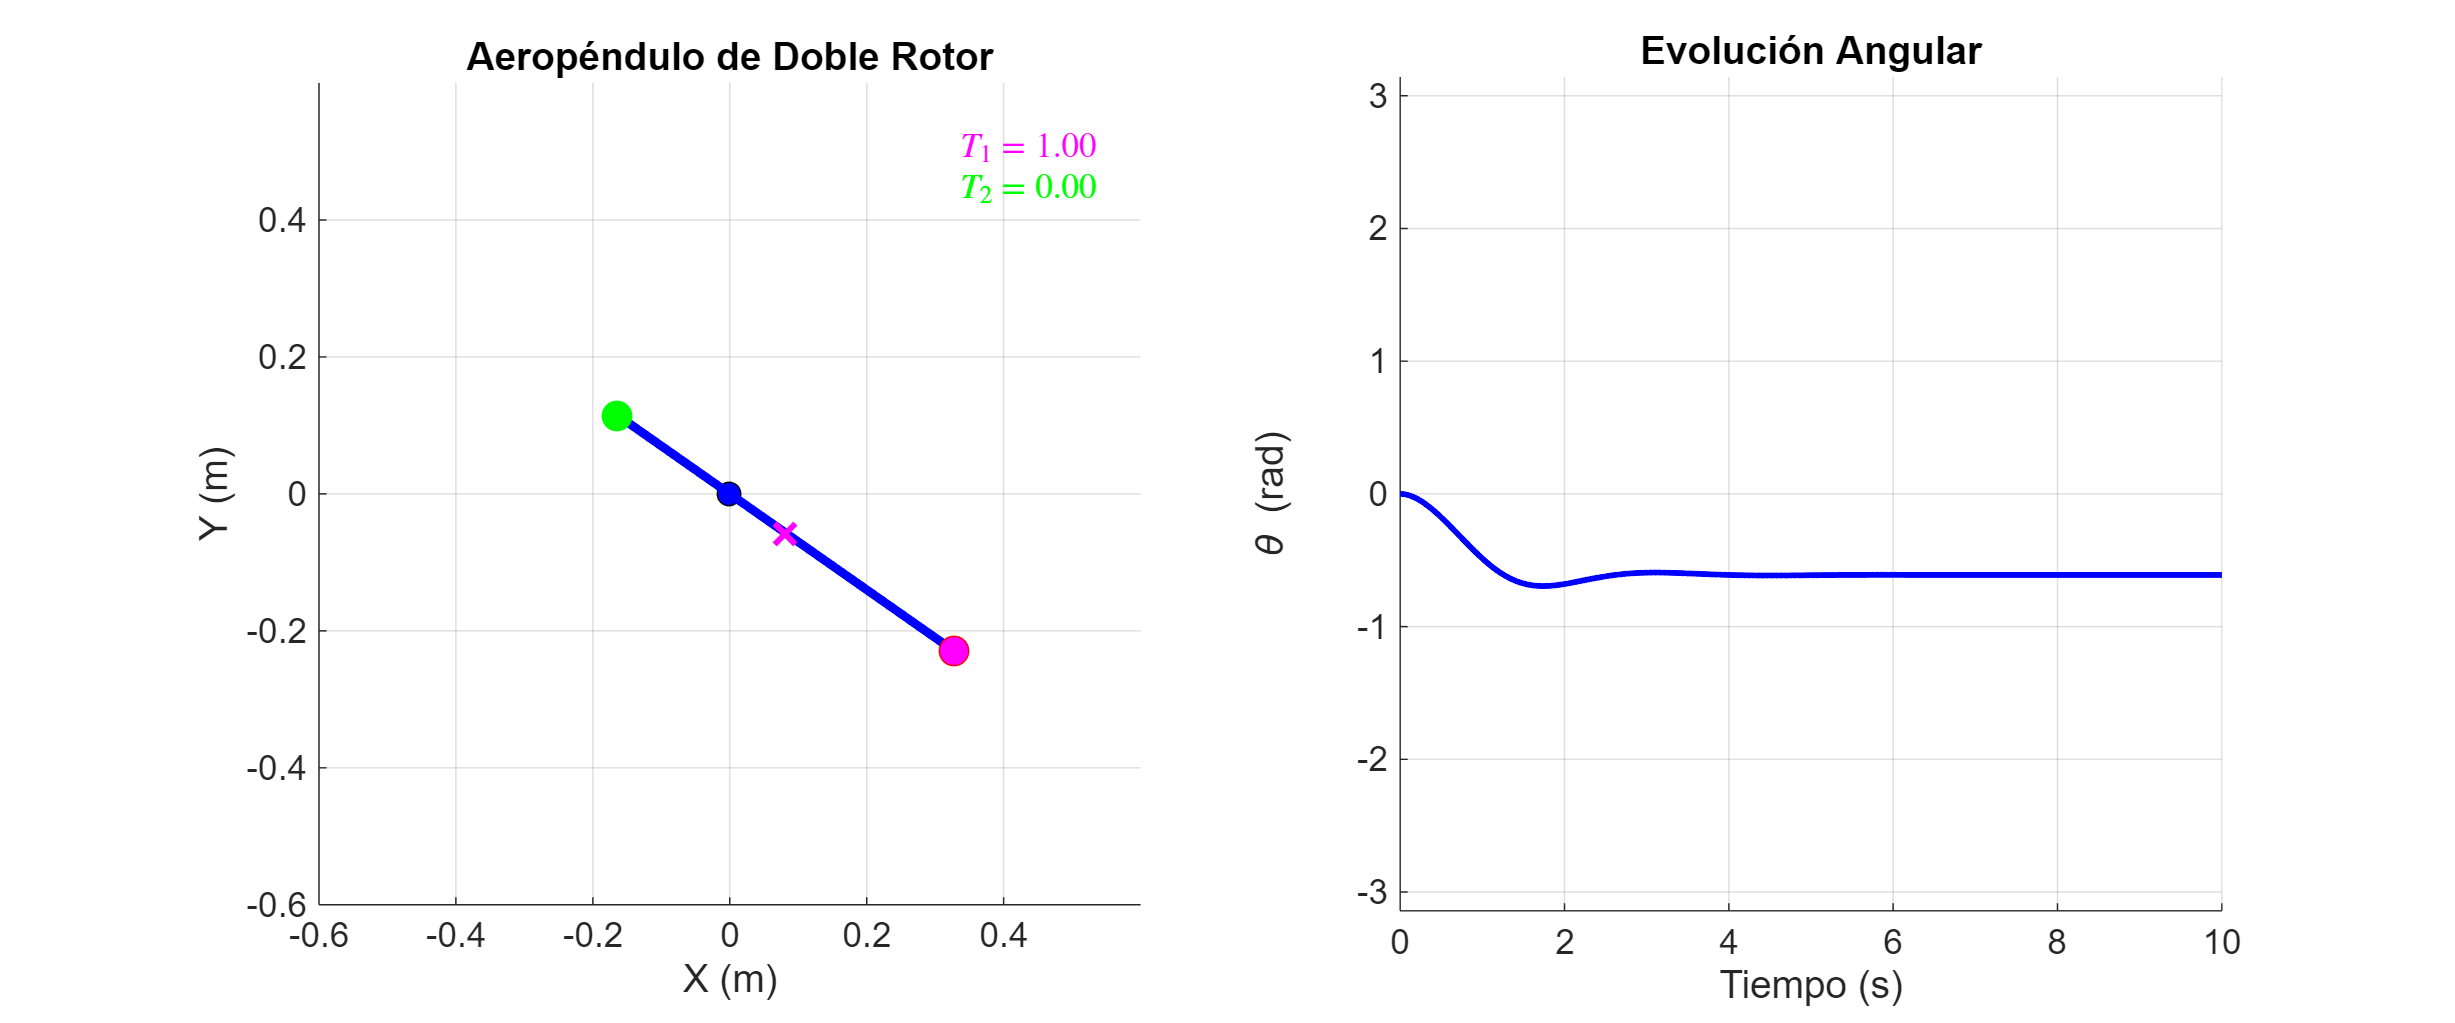

    [T1,T2] = thrust_fun(t,theta,theta_dot);
    
    %% Dinámica del sistema
    theta_ddot = ( ...
          T1*params.l1 ...
        - T2*params.l2 ...
        - params.m*params.g*params.d*sin(pi/2 - theta) ...
        - params.c*theta_dot ...
        ) / params.J;

    
    %% Vector de derivadas
    dx = [theta_dot; theta_ddot];

end
% Modelo de empuje constante para los rotores del aerobalancín.
function [T1,T2] = thrust_constant(~, ~, ~)
% Salidas:
%   T1 -> Empuje generado por el rotor 1 (N)
%   T2 -> Empuje generado por el rotor 2 (N)

    T1 = 1;   % Empuje constante del rotor 1 (N)
    T2 = 1;   % Empuje constante del rotor 2 (N)
end
% Simula la dinámica del aerobalancín
function [t,theta,theta_dot,sol] = simulate_aeropendulum(params,x0,tspan,thrust_fun)

    % Entradas:
    %   params      -> parámetros físicos del sistema
    %   x0          -> condiciones iniciales [theta0; theta_dot0]
    %   tspan       -> vector de tiempo de simulación
    %   thrust_fun  -> función de empuje de los rotores
    %
    % Salidas:
    %   t           -> vector de tiempo
    %   theta       -> posición angular en [-pi,pi]
    %   theta_dot   -> velocidad angular (rad/s)
    %   sol         -> solución completa del sistema

    % Resolver el sistema dinámico (Runge-Kutta 4,5)
    [t,sol] = ode45(@(t,x) aeropendulum_dynamics(t,x,params,thrust_fun), tspan, x0);

    % Variables de estado
    theta = mod(sol(:,1) + pi, 2*pi) - pi;   % mantener en [-pi,pi]
    theta_dot = sol(:,2);

end

function plot_aeropendulum_states(t,theta,theta_dot)
% Entradas:
%   t         -> vector de tiempo (s)
%   theta     -> posición angular (rad)
%   theta_dot -> velocidad angular (rad/s)

    figure
    plot(t,theta,'b','LineWidth',1.5)
    hold on
    plot(t,theta_dot,'r','LineWidth',1.5)
    
    xlabel('Tiempo (s)')
    ylabel('Estados')
    legend('Posición (rad)','Velocidad angular (rad/s)')
    grid on
end

function ep = equilibrium_point(T1, T2, params)

    tau = T1*params.l1 - T2*params.l2;
    arg = tau/(params.m*params.g*params.d);

    ep = sign(tau) .* acos(abs(arg));   % elementwise

    % mask non-physical region
    ep(abs(arg) > 1) = NaN;

end


T1 = linspace(0,5,100);
T2 = linspace(0,5,100);
[T1g,T2g] = meshgrid(T1,T2);

theta_eq = equilibrium_point(T1g, T2g, params);

figure
surf(T1g, T2g, theta_eq)
shading interp
colorbar
xlabel('T_1')
ylabel('T_2')
zlabel('\theta_e (rad)')
title('Equilibrium Angle Surface')
grid on

tspan = linspace(0, 10, 1000);
eq = 35 * pi/180
input= params.m*params.g*params.d*cos(eq)/params.l1
%% ---- Thrust control ----
function [T1,T2] = thrust_control(t, theta, theta_dot)
    % This function will contain in the future the manner in which we will
    % control the thrust on two motors.
    T1 = 1.0045;
    T2 = 0;
end

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_control, params, tspan, x0)